clear all
load("data\longitudinal_data")
load("data\mass_properties")


**Współczynniki masowe kalkulacje**

% I_yy_CG = I_YY_b

I_YY_b = Iyy + Mass* ((x_CG-x_AC_WB(4))^2)

I_YY_b = 7.9655e+06

**Wspolczynniki do macierzy I równania**

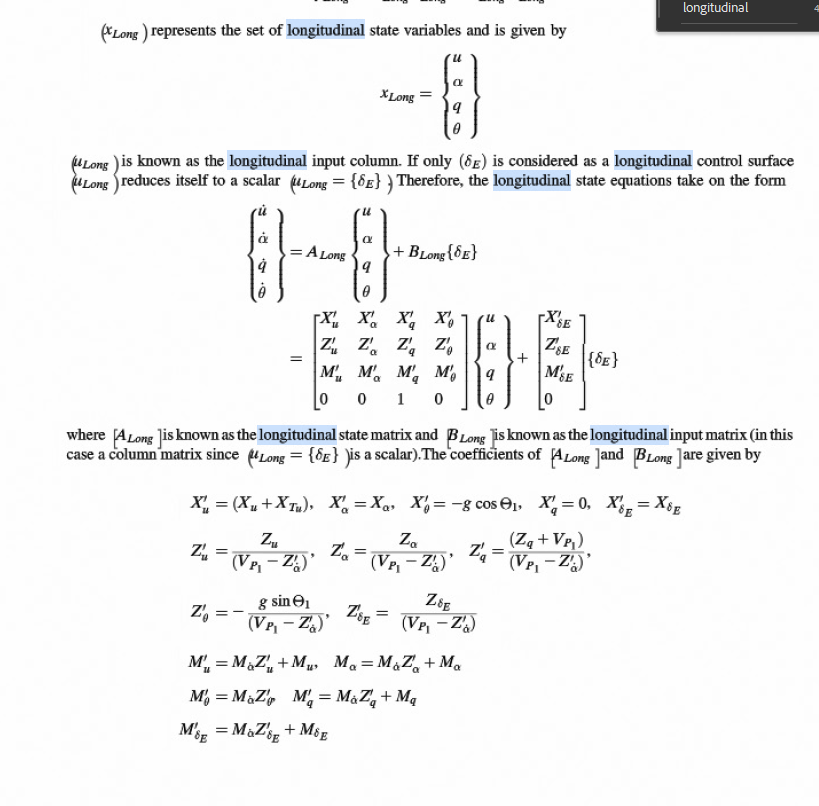

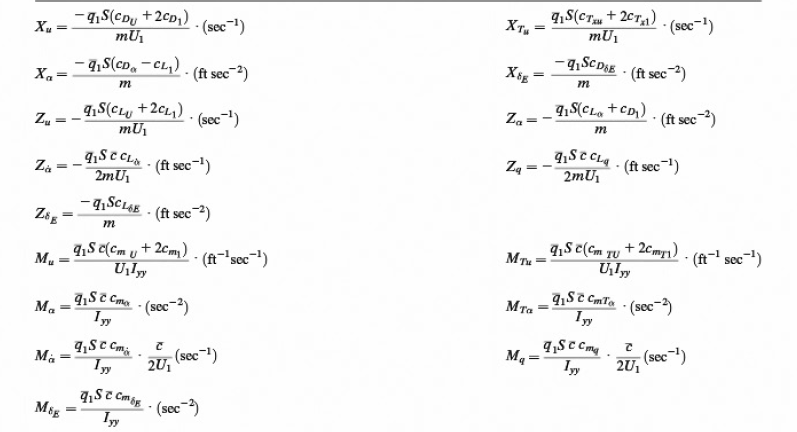

**%%%%%%%%%%%%%%%%%%%%    X   %%%%%%%%%%%%%%%%%%%%%%%%%**

**X'u**

X_u = (-dynamic_pressure(2, 4)*S*(C_Du+(2*C_D1(2, 4))))/ (Mass* Vp1(2, 4))

X_u = -0.0063

X_tu = (dynamic_pressure(2, 4)*S*(C_xTu(2, 4)+2*C_xT1(2, 4)))/(Mass*Vp1(2, 4))

X_tu = -0.0027

dX_u = X_u + X_tu

dX_u = -0.0090

**X'_alpha**

% dX_a = X_a
dX_a = (-dynamic_pressure(2, 4)*S*(C_Da(2, 4)-C_L1(2, 4)))/Mass

dX_a = 16.6938

**X'_theta**

theta_1 = alfa_1(2, 4)

theta_1 = 0.0581

dX_theta = -gravity_acceleration(1)*cos(theta_1)

dX_theta = -32.1157

**X'q**

dX_q = 0

dX_q = 0

**X'delta_e**

% dX_delta_e = X_delta_e
dX_delta_e = -(dynamic_pressure(2, 4)*S*C_Ddelta_E)/Mass

dX_delta_e = 0

**%%%%%%%%%%%%%%%%%%%%    Z   %%%%%%%%%%%%%%%%%%%%%%%%%**

**Z'alpha_dot**

Z_a_dot = (-dynamic_pressure(2, 4)*S*MAC*C_La_dot(4))/(2*Mass*Vp1(2, 4))

Z_a_dot = -2.4311

dZ_a_dot = Z_a_dot/Vp1(2, 4)

dZ_a_dot = -0.0039

%dZ_a_dot = Z_a_dot %uwaga jedna opcja z dwóch

**Z'alpha**

Z_a = (-dynamic_pressure(2, 4)*S*(C_La(4)+C_D1(2, 4)))/Mass

Z_a = -432.2953

dZ_a = Z_a/(Vp1(2, 4) - dZ_a_dot)

dZ_a = -0.6949

**Z'u**

Z_u = ((-dynamic_pressure(2, 4))*S*(C_Lu(2, 4)+2*C_L1(2, 4)))/(Mass*Vp1(2, 4))

Z_u = -0.1325

dZ_u = Z_u/(Vp1(2, 4) - dZ_a_dot)

dZ_u = -2.1305e-04

**Z'q**

Zq = -(dynamic_pressure(2, 4)*S*MAC*C_Lq(4))/(2*Mass*Vp1(2, 4))

Zq = -11.2176

dZ_q = (Zq + Vp1(2, 4))/(Vp1(2, 4) - dZ_a_dot)

dZ_q = 0.9820

**Z'theta**

dZ_theta = -(gravity_acceleration(2)*sin(theta_1))/(Vp1(2, 4) - dZ_a_dot)

dZ_theta = -0.0030

**Z'delta_e**

Z_delta_e = -(dynamic_pressure(2, 4)*S*c_Ldelta_E(4))/Mass

Z_delta_e = -25.7538

dZ_delta_e = Z_delta_e/(Vp1(2, 4)-dZ_a_dot)

dZ_delta_e = -0.0414

**%%%%%%%%%%%%%%%%%%%%    M   %%%%%%%%%%%%%%%%%%%%%%%%%**

**M'a**

M_a_dot = (dynamic_pressure(2, 4)*S*(MAC^2)*C_m_alpha_dot(4))/(2*I_YY_b*Vp1(2, 4))

M_a_dot = -0.2003

M_a = (dynamic_pressure(2 ,4)*S*MAC*C_ma(4))/I_YY_b

M_a = -1.6743

dMa = M_a_dot*dZ_a+M_a

dMa = -1.5351

**M'u**

Mu = (dynamic_pressure(2, 4)*S*MAC*(C_mu(2 ,4)+(2*C_m1)))/(I_YY_b*Vp1(2 ,4))

Mu = -5.7673e-05

dMu = M_a_dot*dZ_u+Mu

dMu = -1.5007e-05

**M'delta_E**

M_delta_E = (dynamic_pressure(2, 4)*S*MAC*C_mdelta_E(4))/I_YY_b

M_delta_E = -1.8033

dM_delta_E = M_a_dot*dZ_delta_e+M_delta_E

dM_delta_E = -1.7950

**M'q**

M_q = ((dynamic_pressure(2, 4)*S*MAC*C_mq(4))/Iyy)*(MAC/(2*Vp1(2, 4)))

M_q = -0.6030

dMq = M_a_dot * dZ_a + M_q

dMq = -0.4638

**M'theta**

dM_theta = M_a_dot*dZ_theta

dM_theta = 6.0165e-04

**Wspolczynniki do macierzy II równania**

**Z''_a**

ddZa = dZ_a*Vp1(2, 4)-gravity_acceleration(1)*sin(theta_1)

ddZa = -434.1616

**Z''_u**

ddZu = dZ_u*Vp1(2, 4)

ddZu = -0.1325

**Z''_q**

ddZq = (dZ_q-1)*Vp1(2, 4)

ddZq = -11.2214

**Z''_theta**

ddZ_theta = dZ_theta*Vp1(2, 4) + gravity_acceleration(1)*sin(theta_1)

ddZ_theta = 1.1740e-05

**Z''_delta_E**

ddZ_delta_E = dZ_delta_e*Vp1(2, 4)

ddZ_delta_E = -25.7536

**%%%%%%%%%%%%%%%%%%%%    MACIERZE   %%%%%%%%%%%%%%%%%%%%%%%%%**

**A**

A = [dX_u dX_a dX_q dX_theta;
    dZ_u dZ_a dZ_q dZ_theta;
    dMu dMa dMq dM_theta;
    0 0 1 0]

A =    -0.0090   16.6938         0  -32.1157
   -0.0002   -0.6949    0.9820   -0.0030
   -0.0000   -1.5351   -0.4638    0.0006
         0         0    1.0000         0


**B**

B = [dX_delta_e;
    dZ_delta_e;
    dM_delta_E;
    0]

B =          0
   -0.0414
   -1.7950
         0


**C**

C = [ddZa ddZu ddZq ddZ_theta;
    1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1]

C =  -434.1616   -0.1325  -11.2214    0.0000
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


**D**

D = [ddZ_delta_E;
    0;
    0;
    0;
    0]

D =   -25.7536
         0
         0
         0
         0


**%%%%%%%%%%%%%%%%%%%%    SIŁOWNIK   %%%%%%%%%%%%%%%%%%%%%%%%%**

c_E = 5

c_E = 5


A_act = [dX_u dX_a dX_q dX_theta 0;
    dZ_u dZ_a dZ_q dZ_theta 0;
    dMu dMa dMq dM_theta 0;
    0 0 1 0 0;
    0 0 0 0 -c_E]

A_act =    -0.0090   16.6938         0  -32.1157         0
   -0.0002   -0.6949    0.9820   -0.0030         0
   -0.0000   -1.5351   -0.4638    0.0006         0
         0         0    1.0000         0         0
         0         0         0         0   -5.0000



B_act = [dX_delta_e 0;
    dZ_delta_e 0;
    dM_delta_E 0;
    0 0;
    0 c_E]

B_act =          0         0
   -0.0414         0
   -1.7950         0
         0         0
         0    5.0000



C_act = [ddZa ddZu ddZq ddZ_theta 0;
    1 0 0 0 0;
    0 1 0 0 0;
    0 0 1 0 0;
    0 0 0 1 0;
    0 0 0 0 1;
    ]

C_act =  -434.1616   -0.1325  -11.2214    0.0000         0
    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    1.0000         0
         0         0         0         0    1.0000



D_act = [ddZ_delta_E 0;
    0 0;
    0 0;
    0 0;
    0 0;
    0 0]

D_act =   -25.7536         0
         0         0
         0         0
         0         0
         0         0
         0         0


**%%%%%%%%%%%%%%%%%%%%    TRANSMITANCJA   %%%%%%%%%%%%%%%%%%%%%%%%%**

M_Ta = (dynamic_pressure(2, 4)*S*MAC*C_mTa)/I_YY_b

M_Ta = 0

M_TU = (dynamic_pressure(2, 4)*S*MAC*(C_mTu(2, 4)+2*C_mT1))/(I_YY_b*Vp1(2, 4))

M_TU = -1.0554e-05


Au = dX_delta_e*(Vp1(2, 4)-Z_a_dot)

Au = 0

Bu = -dX_delta_e*((Vp1(2, 4)-Z_a_dot)*M_q+Z_a+M_a_dot*(Vp1(2, 4)+Z_a))+Z_delta_e*dX_a

Bu = -429.9290

Cu = dX_delta_e*(M_q*Z_a+M_a_dot*gravity_acceleration(2)*sin(theta_1)-(M_a+M_Ta)*(Vp1(2, 4)+Zq))

Cu = 0

Du = gravity_acceleration(1)*sin(theta_1)*dX_delta_e*(M_a+M_Ta)-gravity_acceleration(1)*cos(theta_1)*Z_delta_e*(M_a+M_Ta)+M_delta_E*(gravity_acceleration(2)*cos(theta_1)*Z_a-gravity_acceleration(1)*sin(theta_1)*dX_a)

Du = 2.3708e+04


Aa = Z_delta_e

Aa = -25.7538

Ba = dX_delta_e * Z_u - Z_delta_e*((X_u+X_tu)+M_q)+M_delta_E*(Zq+Vp1(2, 4))

Ba = -1.1174e+03

Ca = dX_delta_e*((Zq+Vp1(2, 4))*(Mu+M_TU)-M_q*Z_u)+Z_delta_e*M_q*(X_u+X_tu)-M_delta_E*(gravity_acceleration(1)*sin(theta_1)+(Zq+Vp1(2, 4))*(X_u+X_tu))

Ca = -6.7307

Da = Z_delta_e*M_a_dot+M_delta_E*(Vp1(2, 4)-Z_a_dot)

Da = -1.1211e+03


At = Z_delta_e*M_a_dot+M_delta_E*(Vp1(2, 4) - Z_a_dot)

At = -1.1211e+03

Bt = dX_delta_e*(Z_u*M_a_dot+(Vp1(2, 4)-Z_a_dot)*(Mu+M_TU))+Z_delta_e*((M_a+M_Ta)*(X_u+X_tu)+dX_a*(Mu+M_TU))-M_delta_E*((Vp1(2, 4)-Z_a_dot)*(X_u+X_tu)-Z_a)

Bt = 769.0170

Ct = dX_delta_e*((M_a+M_Ta)*Z_u-(Mu+M_TU)*Z_a)-Z_delta_e*((M_a+M_Ta)*(X_u+X_tu)+dX_a*(Mu+M_TU))+M_delta_E*((X_u+X_tu)*Z_a-dX_a*Z_u)

Ct = -10.6781


A1 = Vp1(2, 4) - Z_a_dot

A1 = 624.5411

B1 = -(Vp1(2, 4) - Z_a_dot)*(X_u+X_tu+M_q)-Z_a-M_a_dot*(Zq+Vp1(2, 4))

B1 = 936.8860

C1 = (X_u+X_tu)*(M_q*(Vp1(2, 4) - Z_a_dot)+Z_a+M_a_dot*(Vp1(2, 4) - Z_a_dot))+M_q*Z_a-Z_u*dX_a+M_a_dot*gravity_acceleration(1)*sin(theta_1) - (M_a+M_Ta)*(Vp1(2, 4)+Zq)

C1 = 1.2937e+03

D1 = gravity_acceleration(1)*sin(theta_1)*((M_a+M_Ta)-M_a_dot*(X_u+X_tu))+gravity_acceleration(1)*cos(theta_1)*(M_a_dot*Z_u+(Mu+M_TU)*(Vp1(2, 4) - Z_a_dot)) - dX_a *(Mu+M_TU)*(Zq+Vp1(2, 4))+Z_u*dX_a*M_q+(X_u+X_tu)*((M_a+M_Ta)*(Zq+Vp1(2, 4)) - M_q*Z_a)

D1 = 9.9862

E1 = gravity_acceleration(1)*cos(theta_1)*(Z_u*(M_a+M_Ta)-Z_a*(Mu+M_TU))+gravity_acceleration(1)*sin(theta_1)*((Mu+M_TU)*dX_a-(X_u+X_tu)*(M_a+M_Ta))

E1 = 6.1490


D1_dash_roots = roots([A1 B1 C1 D1 E1])

D1_dash_roots =   -0.7479 + 1.2251i
  -0.7479 - 1.2251i
  -0.0021 + 0.0691i
  -0.0021 - 0.0691i


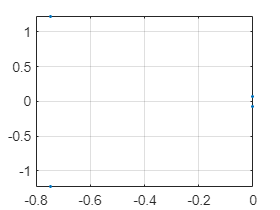

plot(D1_dash_roots, '.')
grid on

**%%%%%%%%%%%%%%%%%%%% ZMIENNE STANU %%%%%%%%%%%%%%%%%%%%%%%%**